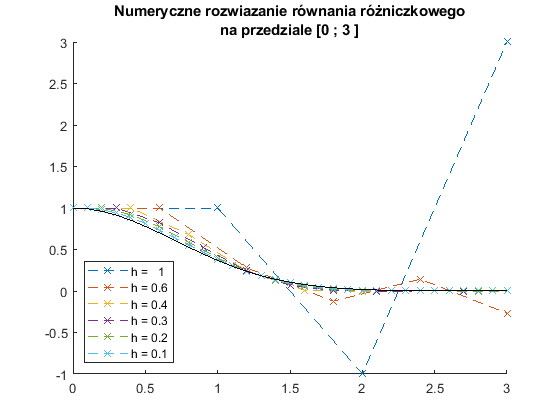



clear all;
close all;
clc





%%%%%%%Definicja zadania
t0 = 0;
tk = 3;
yprim=@(t, y) -2*t*y; %prawa strona rownania rozniczkowego
%warunek poczatkowy bedzie zdefiniowany dla poszczegolnych krokow 

%%%dla ukladu rownan definiujemy prawe strony wszystkich rownan:
%omega=1;
%f1=@(x) x;
%f2=@(x) -omega^2*sin(x);

%%%Rozwiazanie analityczne w celu prezentacji własciwosci numerycznych (zazwyczaj nieznane)
yDokl=@(t) exp(-t.^2);



figure()
plot([],[])
hold on
%H=logspace(0,-1,6);
H=[1, 0.6, 0.4, 0.3, 0.2, 0.1]; %arbitralnie wybrane
leg=[]; %to bedzie wektor etykiet do poszczegolnych serii danych
err=[]; %to beda maksymalne bledy poszczegolnych rozwiazan
for h=H
    
    Y=1; %warunek początkowy (przy okazji nadpisuje rozwiązanie dla poprzedniego kroku)
    %nastepne trzy linijki, to warunek poczatkowy dla ukladu rownan
    %Y=0;
    %Y(1,1)=pi/2;
    %Y(1,2)=0;
    t=t0:h:tk;
    for i=1:length(t)-1
        %y1 = Y(i,1)+h*f1(Y(i,2)); %dla ukladu rownan
        %y2 = Y(i,2)+h*f2(Y(i,1)); %dla ukladu rownan
        yNast= Y(i)+h*yprim(t(i),Y(i)); %tu jest zaimplementowana metoda otwarta Eulera
        %Y=[Y; [y1, y2]]; %dla ukladu rownan
        Y=[Y yNast];
    end
    YDokl=[]; %rozwiazanie dokladne dla punktow odleglych o dany krok
    YDokl=yDokl(t); %rozwiazanie dokladne dla punktow odleglych o dany krok
    err=[err max(abs(YDokl-Y)./YDokl)];
    %plot(t,Y(:,1),'x') %dla ukladu rownan
    plot(t,Y,'--x')
    leg=[leg ; h];
end
%ponizej definicja wykresow
plot(t,YDokl,'k-')
title(['Numeryczne rozwiązanie równania różniczkowego' newline 'na przedziale [' num2str(t0) ' ; ' num2str(tk) ' ]'])
leg=[repelem('h = ',length(H),1), num2str(leg(1:length(H)))];
legend(leg,'location','southwest')
hold off

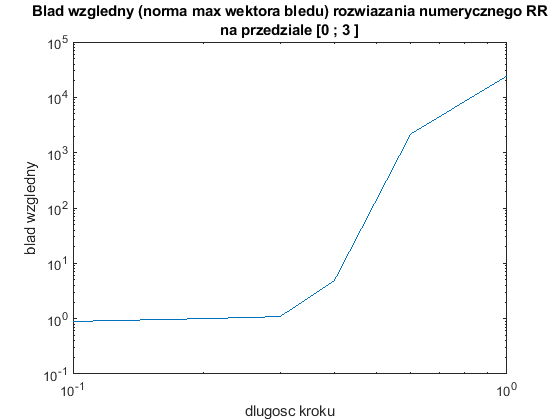

figure()
loglog(H,err)
title(['Blad wzgledny (norma max wektora bledu) rozwiazania numerycznego RR' newline 'na przedziale [' num2str(t0) ' ; ' num2str(tk) ' ]'])
xlabel('dlugosc kroku')
ylabel('blad wzgledny')